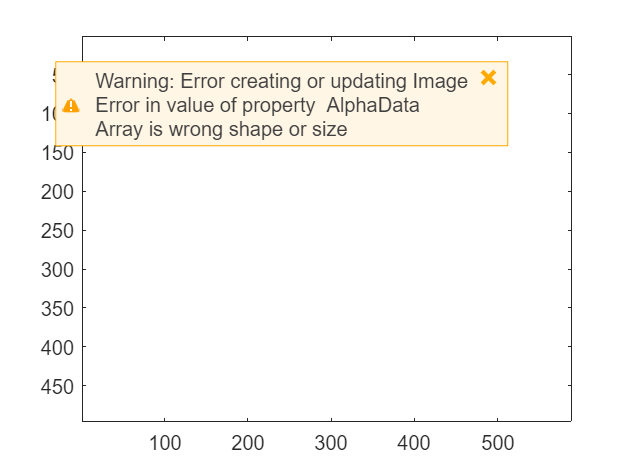

close all
clear all
clc

% %CI
% Y(1)=0;
% v(1)=0; % DERIVADA DE LA CARGA = CORRIENTE

%Variables
v0= 0; %Ohms
Y0=100;
g=9.81;
m=1500;
acel(1)=0;
torre=imread('Torre_Prisma24.png');
torre1=flipud(torre);
torre3=imresize(torre1,[100, 70]);

gond=imread('Magnezone24.png');
[gond,~,gond_alpha]=imread('Magnezone24.png');
gond1 = image(gond, 'alphaData', gond_alpha);

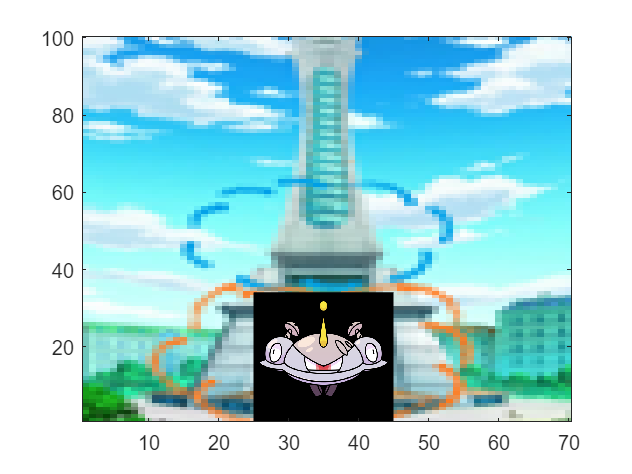


% imwrite(gond, 'Magnezone24.png24.png','Transparency',[0 0 0]);
gond1=flipud(gond);

% img=flipud(img);

%PASO
tf=10;
t0=0;
n=100;
h=(tf-t0)/n;
t=t0:h:tf;


%Funcion
f=@(y, v, t) -g;
a=@(k,v,m) -g+(k*v)/m;
k=0;

%Vectores
Y=zeros(1,n+1);
v=zeros(1,n+1);

Y(1)= Y0;
v(1)= v0;

for i= 1:n

    if Y(i)<=40

        k=-4*m;
        k1= h*v(i);
        L1= h*a(k, v(i), m);
        k2=h*(v(i)+(L1/2));
        L2= h*a(k, v(i)+L1/2, m);
        k3= h*(v(i)+(L2/2));
        L3= h*a(k, v(i)+L2/2, m);
        k4= h*(v(i)+L3);
        L4= h*a(k, v(i)+L3, m);

        Y(i+1)= Y(i)+(1/6)*(k1+2*k2+2*k3+k4);
        v(i+1)= v(i)+(1/6)*(L1+2*L2+2*L3+L4);
        acel(i+1)=a(k,v(i),m);

    elseif Y(i)<=65

        k=-1.3*m;
        k1= h*v(i);
        L1= h*a(k, v(i), m);
        k2=h*(v(i)+(L1/2));
        L2= h*a(k, v(i)+L1/2, m);
        k3= h*(v(i)+(L2/2));
        L3= h*a(k, v(i)+L2/2, m);
        k4= h*(v(i)+L3);
        L4= h*a(k, v(i)+L3, m);

        Y(i+1)= Y(i)+(1/6)*(k1+2*k2+2*k3+k4);
        v(i+1)= v(i)+(1/6)*(L1+2*L2+2*L3+L4);
        acel(i+1)=a(k,v(i),m);
    else
        k1= h*v(i);
        L1= h*f(Y(i), v(i), t(i));
        k2=h*(v(i)+(L1/2));
        L2= h*f(Y(i)+k1/2, v(i)+L1/2, t(i)+h/2);
        k3= h*(v(i)+(L2/2));
        L3= h*f(Y(i)+k2/2, v(i)+L2/2, t(i)+h/2);
        k4= h*(v(i)+L3);
        L4= h*f(Y(i)+k3, v(i)+L3, t(i)+h);
    
        Y(i+1)= Y(i)+(1/6)*(k1+2*k2+2*k3+k4);
        v(i+1)= v(i)+(1/6)*(L1+2*L2+2*L3+L4);
        acel(i+1)=-9.81;
    end

    % image(img)

    if Y(i)<= 0
        break
    end
end


limber=100;
% plot(0,0)
for n=1:length(t)-2
    clf;
    image(torre3)
    hold on
    % rectangle('position',[-2.1,0,0.2,100],'Facecolor','y');%Poste
    % rectangle('position',[-2.1,0,0.2,50],'Facecolor','b');%Poste
    % rectangle('position',[-2.1,0,0.2,20],'Facecolor','g');%Poste
    %r=rectangle('position', [limber, Y(n), 1.2,5], 'Facecolor', 'r', 'Curvature',0.5, 'Edgecolor', 'r');
    % ylim([-3,100])
    % xlim([-3,-1])
    hold on
    image(gond1, 'XData', [25, 45], 'YData', [Y(n) - 25, Y(n)+10]);
    axis xy
    drawnow
    hold off
    %if n ~=length(t)-2
    %delete(r)
    %end
end

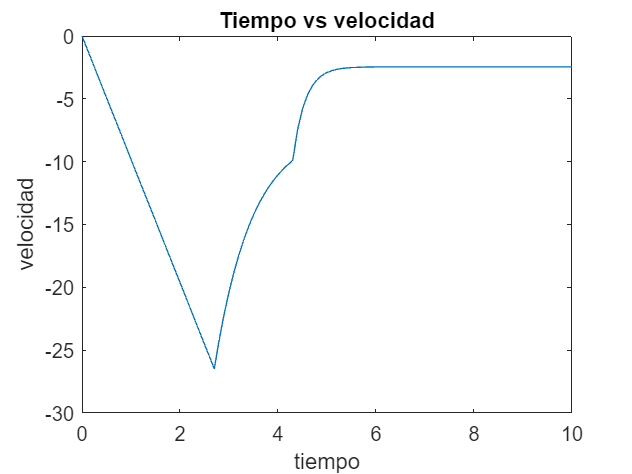

% plot de velocidad
figure
plot(t,v)
title('Tiempo vs velocidad')
xlabel('tiempo')
ylabel('velocidad')
hold off

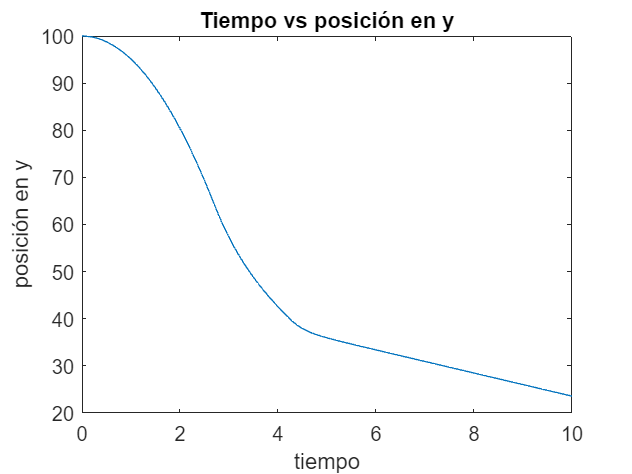


% plot de posición
figure 
plot(t,Y)
title('Tiempo vs posición en y')
xlabel 'tiempo'
ylabel 'posición en y'
hold off

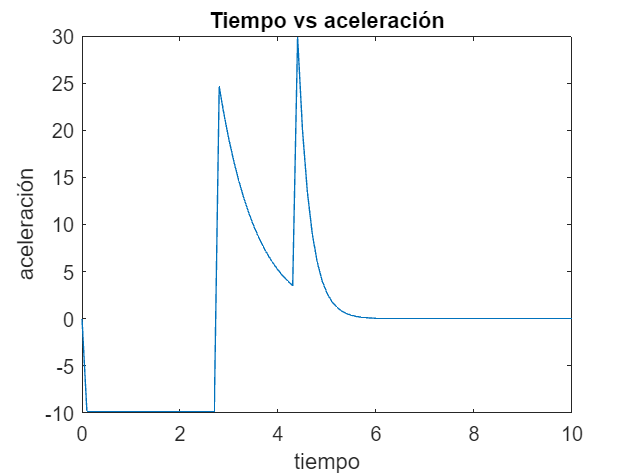


% plot de aceleración
figure
plot(t,acel)
title('Tiempo vs aceleración')
xlabel 'tiempo'
ylabel 'aceleración'